前置补偿器

输入：传递函数G，时间常数T

输出：动态前馈控制器,静态前馈补偿器，预期闭环系统Gm

详见https://zhuanlan.zhihu.com/p/280484938

function [Precomp,precomp_stat,Gm] = Precompensateur(G, T)

s = tf('s');
if class(G) == "ss"
    [num,den] = ss2tf(G.A, G.B, G.C,G.D);
G = tf(num,den);
end


l = length(G.Denominator{1});
precomp_stat = G.Denominator{1}(l)/G.Numerator{1}(l);

p = pole(G);
z = zero(G);
[p,z] = Clean(p,z);

nb_zero_instable = sum(real(z)>=0); 
nb_pole_Prec = nb_zero_instable + length(p) - length(z); %nombre de poles de precompensateur 


前置补偿器

Precompensateur = Gm/G = ......

Precomp = precomp_stat*1/(1+s*T)^nb_pole_Prec;
for i = 1 : length(p)
    
    Precomp = Precomp*(p(i)-s)/p(i);
    
end

for i = 1 : length(z)
    
    if z(i)>0
        Precomp = Precomp;
    else
        Precomp = Precomp*z(i)/(z(i)-s);
    end
    
end

%虽然上面使用了Clean，但是依旧有共轭零极点的虚部在计算中无法被消掉，这里手动消除
Precomp.num=roundn(Precomp.num{1},-3);
Precomp.den=roundn(Precomp.den{1},-3);

Gm

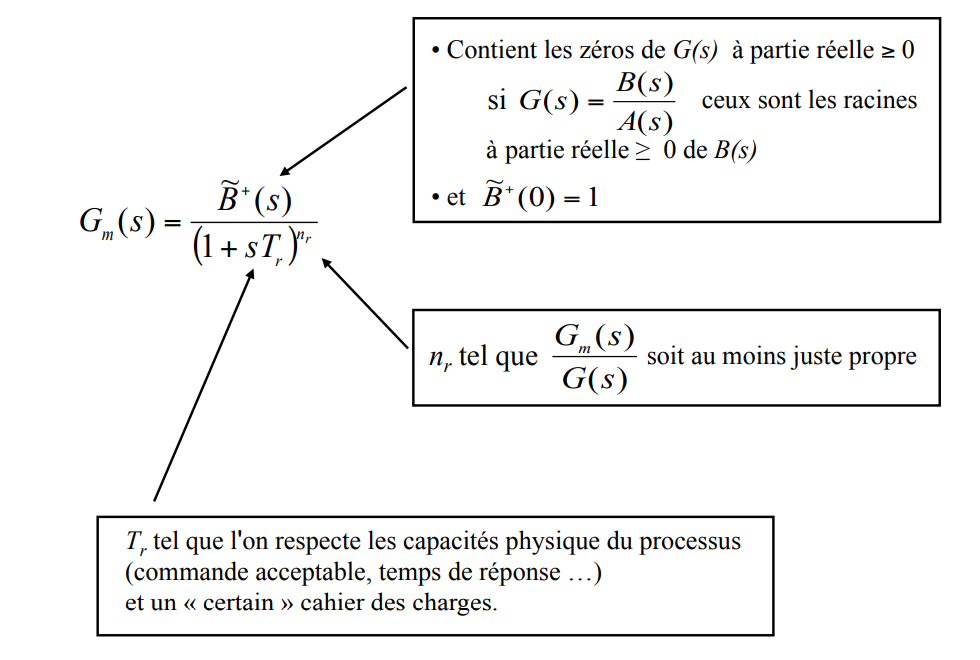

z_instable_index = find(real(z)>=0);
Gm = 1;
for i =1:nb_zero_instable
    
    Gm = (z(z_instable_index(i))-s)*Gm/(z(z_instable_index(i)));
    
end
Gm = Gm/(1+s*T)^nb_pole_Prec;
% Precomp = Gm/G;  理想情况，但数值计算会带来误差导致无法零极互消

figure()
hold on 
step(G)
step(G*Precomp)
step(G*precomp_stat)
step(Gm)
legend('sys','Precomp dyna','Precomp stat','Gm')

end